# 2024-2025-1 数学软件期中考试题

班级：                       姓名：                     学号：                     

**考试时间：110+5分钟    考试形式：闭卷      总分：100**

- 请**先填写上面的班级姓名学号**。

- **闭卷**，只可查看MATLAB的help。在结束前5分钟完成答题，将你的答卷**导出为pdf 文件并提交**。

- 你提交的**文件名应改名为你的班级姓名.pdf**，如“信计1231张三.pdf”。

**一. 填空题：(4分 **$\times$ **10=40分)**

(1) 下列的字符串，**哪些**可以作为MATLAB的变量名（    B，C    ）。

A. xinji@1231      B. xinji1232       C. xinji_1233        D.  xinji-1234

(2)  在MATLAB中，**分别**用冒号表达式和函数linspace()建立一个起点为 $-\pi$，终点为 $\pi$，步长为 $\frac{\pi}4$ 的数组 x.

x=-pi:pi/4:pi

x =    -3.1416   -2.3562   -1.5708   -0.7854         0    0.7854    1.5708    2.3562    3.1416


x=linspace(-pi,pi,9)

x =    -3.1416   -2.3562   -1.5708   -0.7854         0    0.7854    1.5708    2.3562    3.1416


% 以下是建立符号数组
x=-sym(pi):pi/4:pi

$$x = \left(\begin{array}{ccccccccc} -\pi & -\frac{3\,\pi }{4} & -\frac{\pi }{2} & -\frac{\pi }{4} & 0 & \frac{\pi }{4} & \frac{\pi }{2} & \frac{3\,\pi }{4} & \pi \end{array}\right)$$

x=linspace(-sym(pi),pi,9)

$$x = \left(\begin{array}{ccccccccc} -\pi & -\frac{3\,\pi }{4} & -\frac{\pi }{2} & -\frac{\pi }{4} & 0 & \frac{\pi }{4} & \frac{\pi }{2} & \frac{3\,\pi }{4} & \pi \end{array}\right)$$

(3)  在MATLAB中，**不直接输入**，用命令生成矩阵 $A=\left(\begin{array}{ccc}3&1&1\\1&3&1\\1&1&3\end{array}\right)$，再用一条命令将第 2, 3 行减去第1行的 $\frac13$.

A=ones(3)+2*eye(3)

A =      3     1     1
     1     3     1
     1     1     3


A(2:3,:)=A(2:3,:)-A(1,:)/3

A =     3.0000    1.0000    1.0000
         0    2.6667    0.6667
         0    0.6667    2.6667


(4) 以下代码运行时将出错，其错误原因是：（   将函数名sqrt当做自定义的变量名   ）  

sqrt=sqrt(2);
sqrt=sqrt(3);

(5) 用MATLAB命令判断下列线性方程组 $\left(\begin{array}{ccc} 2&1&1\\1&2&1\\1&1&2\end{array}\right)\left(\begin{array}{c}x_1\\x_2\\x_3\end{array}\right)=\left(\begin{array}{c}9\\10\\13\end{array}\right)$是否有解，若有解则求出其解。

A=ones(3)+eye(3);
b=[9;10;13];
rank(A)==rank([A,b])

ans = logical
   1


A\b

ans =     1.0000
    2.0000
    5.0000


(6) 已知矩阵 $M=\left(\begin{array}{ccc} 2&1&1\\1&2&1\\1&1&2\end{array}\right)$，求它的各行元素之和、行列式、特征值. 

M=ones(3)+eye(3);
sum(M,2)

ans =      4
     4
     4


det(M)

ans = 4

eig(M)

ans =     1.0000
    1.0000
    4.0000


(7) 建立符号函数 $f(x) = {\rm e}^x\cos 2x$，并做下列操作：

      (a) 求二阶导； (b) 求 $\displaystyle\int_0^{\pi/2} f(x) dx.$

syms x
f=exp(x)*cos(2*x)

$$f = \cos\left(2\,x\right)\,{\mathrm{e}}^{x}$$

diff(f,2)

$$ans = -3\,\cos\left(2\,x\right)\,{\mathrm{e}}^{x}-4\,\sin\left(2\,x\right)\,{\mathrm{e}}^{x}$$

int(f,x,[0,pi/2])

$$ans = -\frac{{\mathrm{e}}^{\pi /2}}{5}-\frac{1}{5}$$

(8) 对函数 $y=\ln(x+1)$ 作Taylor展开至 7 次多项式.

syms x
y=log(x+1);
taylor(y,x,'order',8)

$$ans = \frac{x^{7}}{7}-\frac{x^{6}}{6}+\frac{x^{5}}{5}-\frac{x^{4}}{4}+\frac{x^{3}}{3}-\frac{x^{2}}{2}+x$$

(9) 在MATLAB中，求方程 $\frac{x\cos(2x)}{1+x^2}=0$ 在 x0= 4 附近的根。

f=@(x)x*cos(2*x)/(1+x^2);
fzero(f,4)

ans = 3.9270

(10) 在MATLAB中，求函数 $f(x)=\frac{x\cos(2x)}{1+x^2}$ 在(4, 6)上的极小值点及极小值。

f=@(x)x*cos(2*x)/(1+x^2);
[x,fval]=fminbnd(f,4,6)

x = 4.6637

fval = -0.2040

**二. 程序设计题，以下8个题任选5个完成（5、8题至少选1个），每题12分。**

1. 已知圆周率的一个近似计算公式为： 


$$\pi=3+\sum\limits_{n=2}^{\infty}\frac{(-1)^n}{(n-1)n(2n-1)},$$


分别用循环和数组运算求 $\pi$ 的近似值，计算 n 从2到100 的级数和，并用 fprintf 输出小数点后15位小数。

% 以下用循环求级数和
mypi=3;
up=1;
for n=2:100    
    down=(n-1)*n*(2*n-1);
    mypi=mypi+up/down;
    up=-up;
end
fprintf('圆周率的近似值为：%.15f',mypi)

圆周率的近似值为：3.141592903558554

% 以下用数组运算求级数和
n=2:100;
up=(-1).^n;
down=(n-1).*n.*(2*n-1);
mypi=3+sum(up./down);
fprintf('圆周率的近似值为：%.15f',mypi)

圆周率的近似值为：3.141592903558553

2. 已知一个函数 $y=f(x)$上的若干个采样点的取值如下表所示：

        
$$\begin{array}{c|c|c|c|c|c|c|c|c}x &0.1&0.4&0.7&1.0&1.3&1.6&1.9&2.2\\\hline y&0.1&0.24&0.08&-0.21&-0.41&-0.45&-0.33&-0.12\end{array}$$


用4次多项式作拟合，求拟合函数的系数向量p。并在同一坐标系中用红色圆圈表现采样点，用蓝色实线表现拟合函数(取步长为0.02)，给出图例。

x=0.1:0.3:2.2;
y=[0.1,0.24,0.08,-0.21,-0.41,-0.45,-0.33,-0.12];
p=polyfit(x,y,4)

p =    -0.4022    2.3756   -4.2786    2.1794   -0.0798


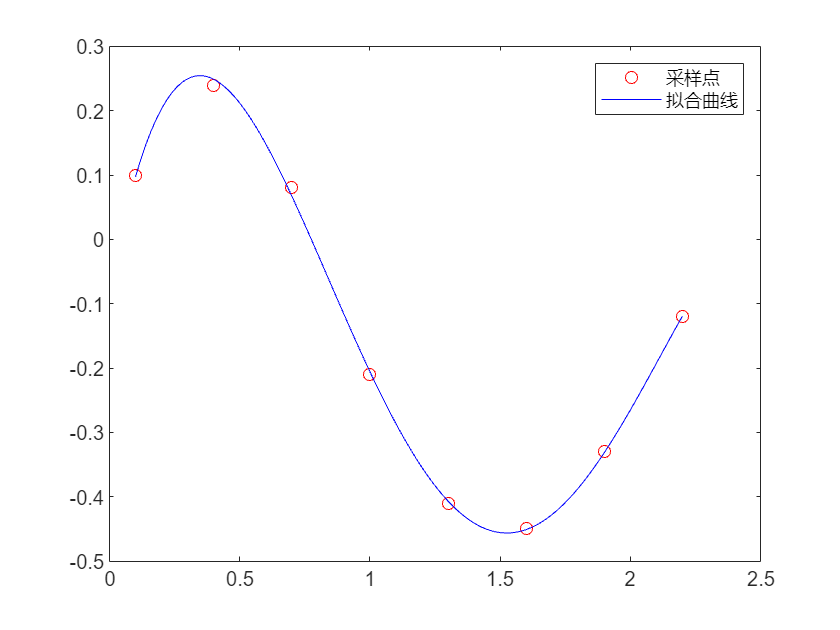

xnew=0.1:0.02:2.2;
ynew=polyval(p,xnew);
figure
plot(x,y,'ro',xnew,ynew,'b')
legend('采样点','拟合曲线')

3. 据世界能源统计年鉴2024，各主要工业国2023年的发电量如下表所示（单位：万亿度）

 
$$\begin{array}{c|c|c|c|c|c|c}\text{国家}&\text{中国}&\text{美国}&\text{印度}&\text{俄罗斯}&\text{日本}&\text{其他}\\\hline \text{发电量}&9.45&4.49&1.96&1.18&1.04&11.78\end{array}$$


请在同一图形窗口中，分左右子图表现上述数据，左子图中用条形图表现各国发电量，横坐标为国家名，标题为“各国发电量”；右子图中用饼图表现所占比例，标题为“比例”。

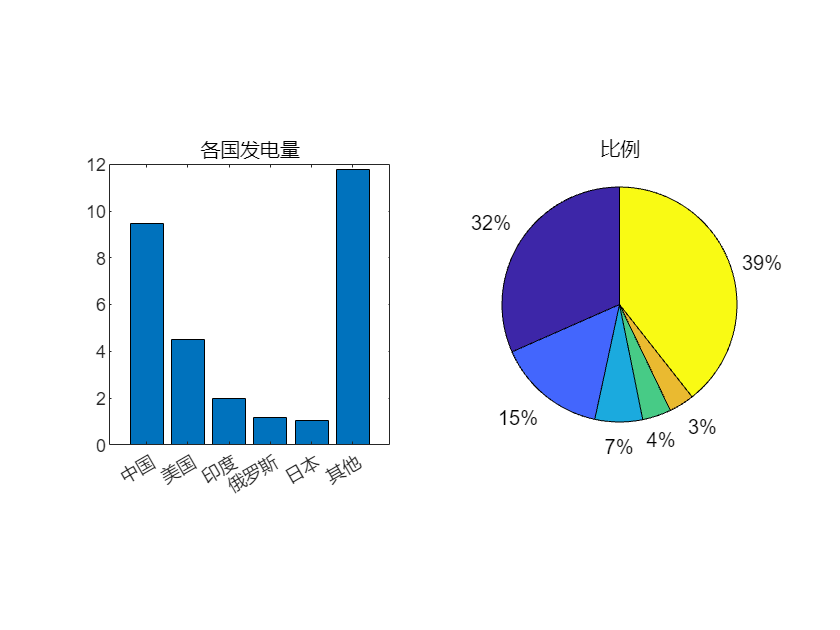

electric=[9.45,4.49,1.96,1.18,1.04,11.78];
country=["中国","美国","印度","俄罗斯","日本","其他"];
% country={'中国','美国','印度','俄罗斯','日本','其他'];
figure,
subplot(121),bar(country, electric),axis square
title('各国发电量')
subplot(122), pie(electric)
title('比例')

4.  在同一图形窗口中，分左右子图，绘制函数 $z=3{\rm e}^{-x^2-y^2}\cos(x^2-y^2)$分别在方域 $x,y\in[-3,3]$上的图形和在圆域 $x^2+y^2\leq9$上的图形。坐标轴上采用等长刻度。

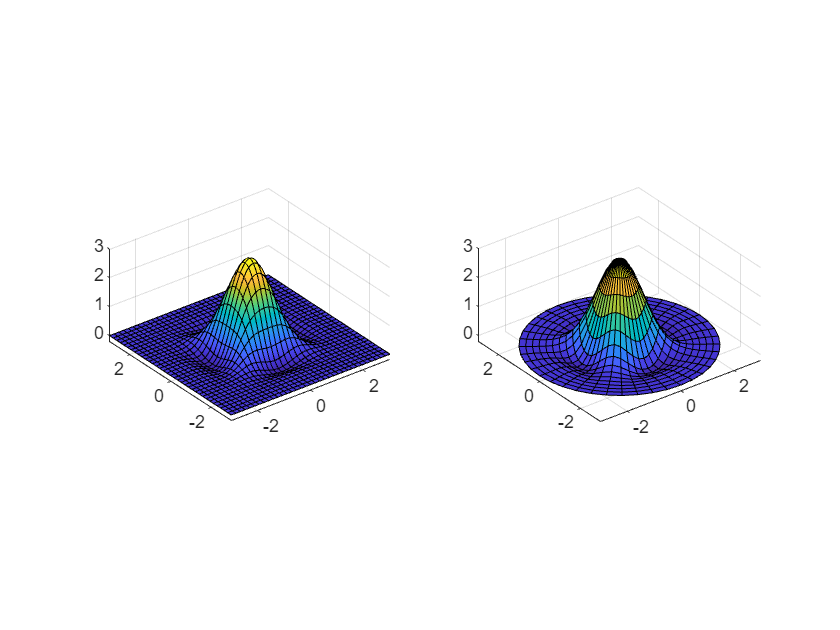

figure
subplot(121)
fsurf(@(x,y)3*exp(-x.^2-y.^2).*cos(x.^2-y.^2), [-3,3,-3,3])
axis equal
t=-pi:pi/20:pi;
r=0:0.2:3;
[t,r]=meshgrid(t,r);
x=r.*cos(t);
y=r.*sin(t);
z=3*exp(-r.^2).*cos(x.^2-y.^2);
subplot(122)
surf(x,y,z), axis equal

5. 求解优化问题： $\max\limits_x(5x_1+2x_2+3x_3)\\ {\rm s.t.} \begin{cases}x_1-x_2-x_3\leq 10,\\-x_1+x_2-2x_3\geq 1,\\x_1+3x_2+x_3=5,\\x_1\geq0,x_3\geq-2.\end{cases}$

f=[5,2,3];
A=[1,-1,-1;1,-1,2];
b=[10,-1];
Aeq=[1,3,1];beq=5;
lb=[0,-inf,-2];
[x,fval]=linprog(-f,A,b,Aeq,beq,lb)

找到最优解。



x =     4.0000
    1.0000
   -2.0000


fval = -16

fval=-fval

fval = 16

6. 求解优化问题： $\begin{array}{l}\min\limits_x f(x)=2x_1^2-3x_1x_2+3x_2^2-9x_1-5x_2,\\{\rm s. t.}\begin{cases}x_1-2x_2=0.5,\\2x_1+x_2\leq3,\\ 3x_1+2x_2\leq6,\\  x_1, x_2\geq0.\end{cases}\end{array}$

H=[4,-3;-3,6];
f=-[9,5];
A=[2,1;3,2]; b=[3,6];
Aeq=[1,-2]; beq=0.5;
lb=[0,0];
[x,fval]=quadprog(H,f,A,b,Aeq,beq,lb)

7.  一个数本身是素数，依次从个位开始去掉1位，2位...，所得的各数仍然是素数，则称为超级素数，如379是素数，去掉末尾的9后，37是素数，再去掉7，3还是素数，故379是超级素数。编写程序，求[100, 999]之内所有超级素数。注：判断素数可用MATLAB自有函数 isprime().

ps=[];


找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


x =     1.3000
    0.4000


fval = -11.4000

for num=100:999
    n1=fix(num/10);
    n2=fix(n1/10);
    if isprime(num)&&isprime(n1)&&isprime(n2)
        ps=[ps,num];
    end
end
disp(['超级素数有：',num2str(ps)])

8. 求数字 $C$ 的平方根 $\sqrt{C}$ 的一种迭代公式为 $x_{k+1}=\frac12(3x_k-\frac{x_k^3}{C}).$ 编写程序，利用该公式求 $\sqrt{3}$。迭代初始值可以取 $x_0=1$，当满足 $|x_{k+1}-x_k| < 10^{-8}$ 时，停止迭代，并取 $x_{k+1}$为平方根的近似值，最后输出$\sqrt{3}$的近似值，保留小数点后8位。

C=3;

超级素数有：233  239  293  311  313  317  373  379  593  599  719  733  739  797


x0=1;
x1=((3*x0)-x0^3/C)/2;
while abs(x1-x0)>=1e-8
    x0=x1;
    x1=((3*x0)-x0^3/C)/2;
end
fprintf('3的平方根的近似值为：%.8f', x1)

以下将求平方根的迭代过程定义为一个函数 mysqrt(C, tol)

x=mysqrt(3, 1e-8);

3的平方根的近似值为：1.73205081

fprintf('3的平方根的近似值为：%.8f', x)

% 以上的各题如果需要定义函数的话，请写在以下的代码框中：

function x=mysqrt(C, tol)
%MYSQRT: 求平方根（第8题函数定义）

3的平方根的近似值为：1.73205081

% mysqrt(C, tol): 求数C的平方根，tol为收敛精度
x0=1;
x=((3*x0)-x0^3/C)/2;
while abs(x-x0)>=tol
    x0=x;
    x=((3*x0)-x0^3/C)/2;
end
end